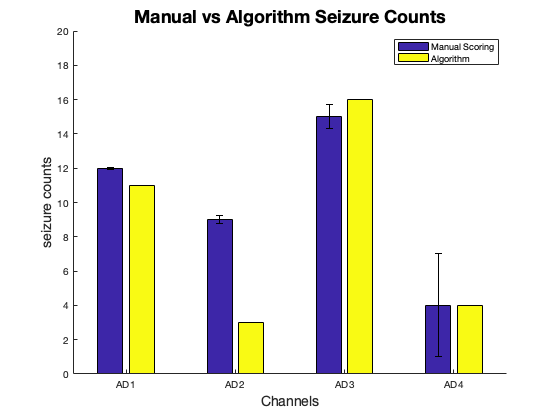


adMan = [12 9 15 4];
adManStDev = [0.05 0.22 0.7 3];
adAlg = [11 3 16 4];
adAlgStDev = [0 0 0 0];

compScore = [adMan;adAlg];
compScore = compScore';
compStDev = [adManStDev; adAlgStDev];
compStDev = compStDev';

ngroups = size(compScore, 1);
nbars = size(compScore, 2);

figure 
b = bar(compScore,'FaceColor', 'flat');
for k = 1:nbars
    b(k).CData = k;
end



hold on


% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
% Set the position of each error bar in the centre of the main bar
% Based on barweb.m by Bolu Ajiboye from MATLAB File Exchange
for i = 1:nbars
    % Calculate center of each bar
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    errorbar(x, compScore(:,i), compStDev(:,i), 'k', 'linestyle', 'none');
end
xlabel ('Channels','fontsize',14);
ylabel ('seizure counts','fontsize',14);
title('Manual vs Algorithm Seizure Counts','fontsize',18);
box 'off'
ylim([0 20])
set(gca,'xtickLabel',{'AD1' 'AD2' 'AD3' 'AD4'});
legend('Manual Scoring', 'Algorithm')

saveas(gcf,'savenamehere.eps','-epsc')


